% Mohamed Ramzan / Start Date: 07/17/2024
% The Cat Breed Images Classification
% Dataset consists of 5,499 images from 11 distinct classes.

% Close all open figures
close all;

% Clear the workspace and command window
clear;
clc;


### Create an Image Datastore

imds = imageDatastore("Dog_breed", 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

Display the number of images in the Image Datastore

numImages = numel(imds.Files);
disp(['Number of images in the datastore: ', num2str(numImages)]);

Number of images in the datastore: 1891


Count Each Label

labelCount = countEachLabel(imds) % Count the image labels from the datastore

labelCount = 11×2 table
          Label           Count
    __________________    _____

    Australian Terrier     187 
    Blenheim Spaniel       187 
    Brittany Spaniel       150 
    English Springer       159 
    German Shepherd        147 
    Komondor               151 
    Maltese Dog            245 
    Norfolk Terrier        172 
    Norwegian              191 
    Otterhound             151 
    Vizsla                 151 


Display 20 Random images in the datastore

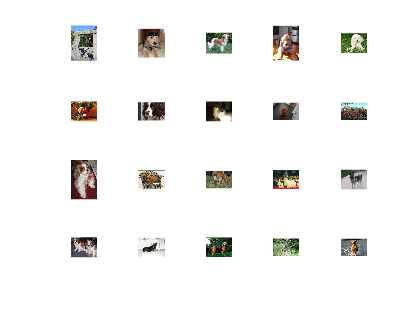

perm = randperm(numImages, 20); % Randomly select 20 images
figure;
for i = 1:20
    subplot(4, 5, i); % Create a 4x5 grid layout
    imshow(readimage(imds, perm(i))); % Display the randomly selected image
end

Read image sizes

img = readimage(imds, 1);
disp('Size of a sample image:');

Size of a sample image:


disp(size(img));

   218   250     3



% Define image size based on AlexNet input requirements
imageSize = [227 227 3]; % AlexNet expects images of size 227x227x3

### Split Dataset into Training (70%), Validation (15%), and Testing (15%)

[imdsTrain, imdsRemain] = splitEachLabel(imds, 0.7, 'randomized');
[imdsValidation, imdsTest] = splitEachLabel(imdsRemain, 0.5, 'randomized');

% Display the number of images in each set
numTrainImages = numel(imdsTrain.Files);
numValidationImages = numel(imdsValidation.Files);
numTestImages = numel(imdsTest.Files);

disp(['Number of training images: ', num2str(numTrainImages)]);

Number of training images: 1325


disp(['Number of validation images: ', num2str(numValidationImages)]);

Number of validation images: 286


disp(['Number of testing images: ', num2str(numTestImages)]);

Number of testing images: 280


% Data Augmentation
% Specify the augmentation operations to use
imageAugmenter = imageDataAugmenter( ...
    'RandRotation', [-45 45], ...
    'RandXScale', [0.8 1.2], ...
    'RandYScale', [0.8 1.2]);

% Create the augmented datastores for training, validation, and test sets
augmentedTrainData = augmentedImageDatastore(imageSize, imdsTrain, ...
    'DataAugmentation', imageAugmenter, ...
    'OutputSizeMode', 'resize', 'ColorPreprocessing', 'gray2rgb');

augmentedValidationData = augmentedImageDatastore(imageSize, imdsValidation, ...
    'OutputSizeMode', 'resize', 'ColorPreprocessing', 'gray2rgb');

augmentedTestData = augmentedImageDatastore(imageSize, imdsTest, ...
    'OutputSizeMode', 'resize', 'ColorPreprocessing', 'gray2rgb');

### Load Pretrained Network

net = alexnet;

% Visualization of the network architecture and detailed information about the network layers
analyzeNetwork(net);

% Read the size of input layer.(input images size)
inputSize = net.Layers(1).InputSize;

% Replace Final Layers
layersTransfer = net.Layers(1:end-3); % Get all layers except the last 3 layers

numClasses = numel(categories(imds.Labels));
layers = [ 
    layersTransfer
    fullyConnectedLayer(numClasses, 'WeightLearnRateFactor', 20, 'BiasLearnRateFactor', 20) % Fully connected layer
    softmaxLayer
    classificationLayer];

% Specify Training Options
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 10, ...
    'MaxEpochs', 15, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augmentedValidationData, ...
    'ValidationFrequency', 3, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

### Train Network Using Training Data

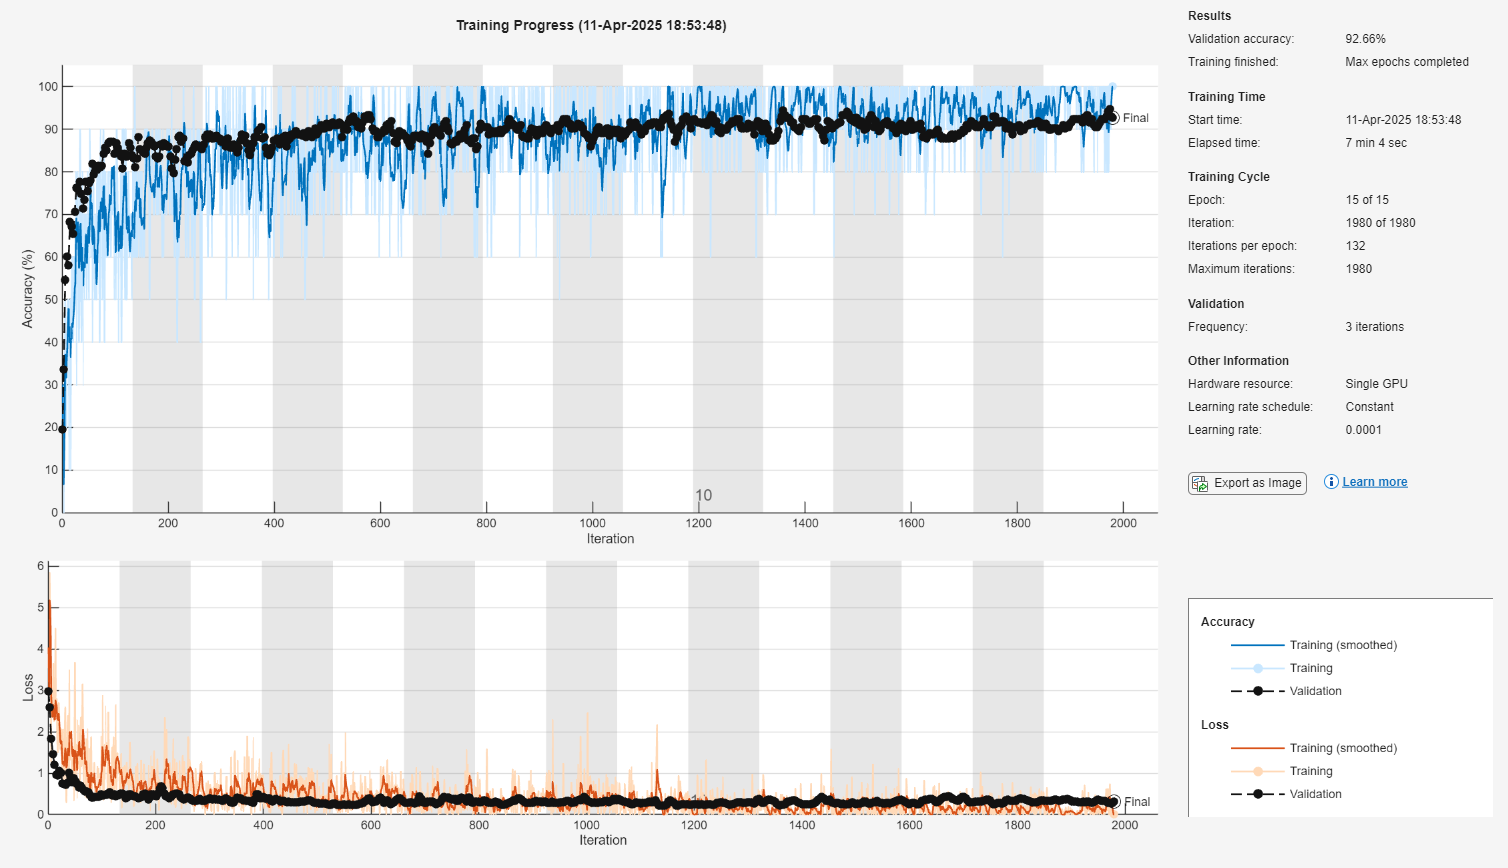

[netTransfer,infoNetTransfer] = trainNetwork(augmentedTrainData, layers, options);

% Specify the filename for saving the model
 filename = 'trainedModelDog.mat';

% Save the trained model to a .mat file
 save(filename, 'netTransfer');

% Classify Test Images and Compute Accuracy 
predictedLabel = classify(netTransfer, augmentedTestData); % Predicted labels for the testing images
testDataTrueLabel = imdsTest.Labels; % True labels of the test data images    


% Display the Test Accuracy score
accuracy = sum(predictedLabel == testDataTrueLabel) / numel(testDataTrueLabel);
disp(['Test Accuracy: ', num2str(accuracy)]);

Test Accuracy: 0.9


### Confusion Matrix

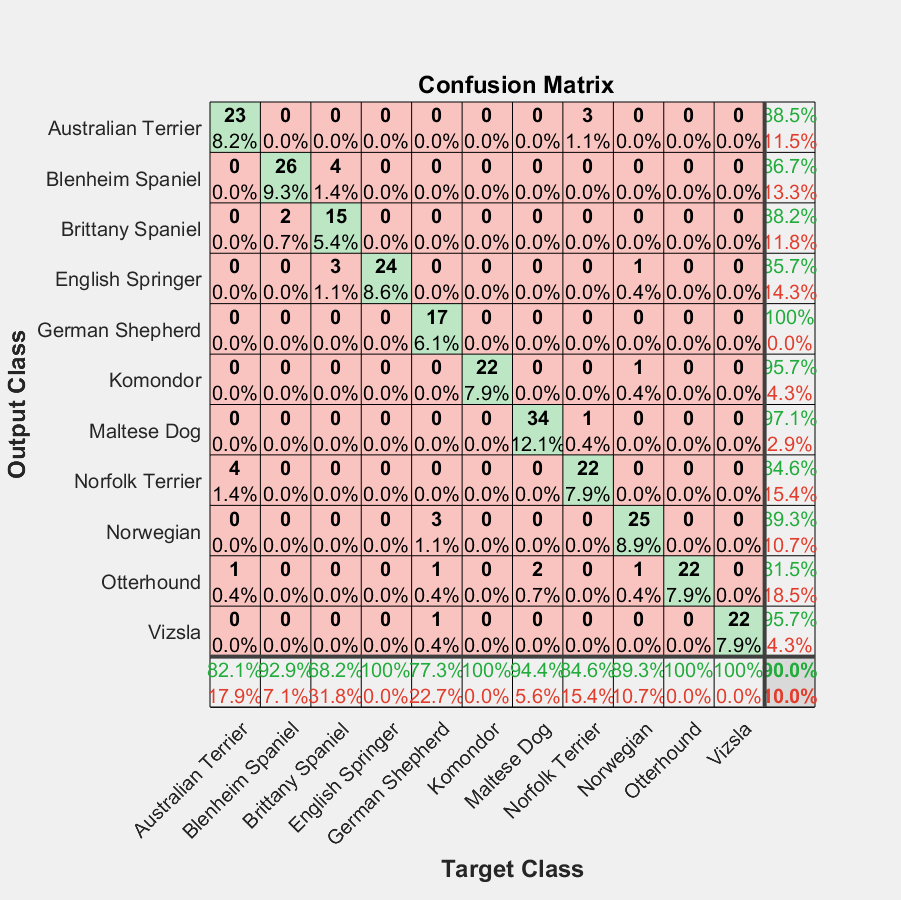

% Confusion Matrix
figure;
plotconfusion(testDataTrueLabel, predictedLabel);

### Precision, Recall, F1 Score, and Error Rate Bar Chart

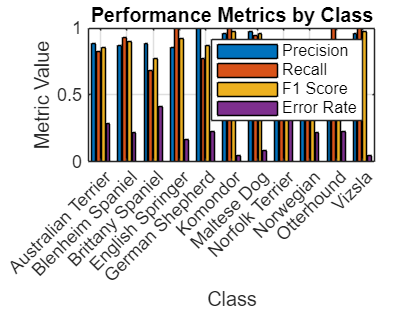

% Compute precision, recall, F1 score, and error rate
confMat = confusionmat(testDataTrueLabel, predictedLabel);
TP = diag(confMat); % True Positives
FP = sum(confMat, 1)' - TP; % False Positives
FN = sum(confMat, 2) - TP; % False Negatives
TN = sum(confMat(:)) - (TP + FP + FN); % True Negatives

% Calculate precision, recall, F1 score, and error rate for each class
precision = TP ./ (TP + FP);
recall = TP ./ (TP + FN);
f1Score = 2 * (precision .* recall) ./ (precision + recall);
errorRate = (FP + FN) ./ sum(confMat, 2);

% Store metrics in a matrix for easy plotting
metrics = [precision recall f1Score errorRate];

% Define class labels
labelNames = categories(imds.Labels); % Automatically get class labels from the data store

% Define metric labels
metricLabels = {'Precision', 'Recall', 'F1 Score', 'Error Rate'};

% Create a grouped bar chart
figure;
bar(metrics);
set(gca, 'XTickLabel', labelNames);
legend(metricLabels);
title('Performance Metrics by Class');
ylabel('Metric Value');
xlabel('Class');
ylim([0 1]); % since metrics are generally between 0 and 1
grid on;

### Confusion Matrix Heatmap

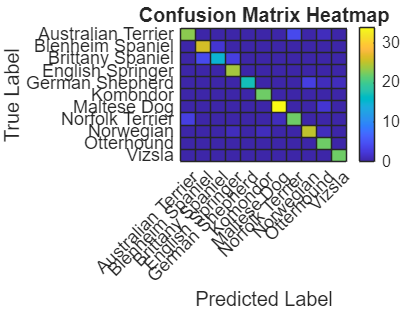

% Confusion Matrix
confMat = confusionmat(testDataTrueLabel, predictedLabel);

% Get class labels
classLabels = categories(imds.Labels);

% Create a confusion matrix heatmap
figure;
h = heatmap(classLabels, classLabels, confMat, 'Colormap', parula, 'ColorbarVisible', true);

% Set heatmap title and labels
title('Confusion Matrix Heatmap');
xlabel('Predicted Label');
ylabel('True Label');

% Enhance the heatmap visualization
h.XDisplayLabels = classLabels;
h.YDisplayLabels = classLabels;

### **Accuracy Plot Over Epochs**

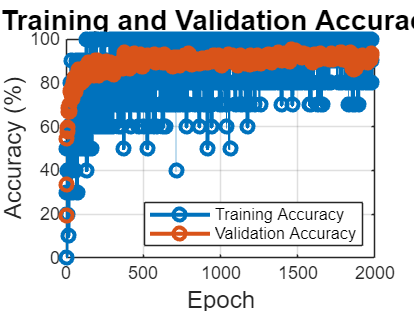

% Extract training and validation accuracy
trainingAccuracy = infoNetTransfer.TrainingAccuracy;
validationAccuracy = infoNetTransfer.ValidationAccuracy;
epochs = 1:length(trainingAccuracy); % Assuming 1:15 epochs

% Plotting the accuracy
figure;
plot(epochs, trainingAccuracy, '-o', 'LineWidth', 2, 'DisplayName', 'Training Accuracy');
hold on;
plot(epochs, validationAccuracy, '-o', 'LineWidth', 2, 'DisplayName', 'Validation Accuracy');
xlabel('Epoch', 'FontSize', 12);
ylabel('Accuracy (%)', 'FontSize', 12);
title('Training and Validation Accuracy', 'FontSize', 14);
legend('show', 'Location', 'SouthEast');
grid on;

### **ROC Curves**

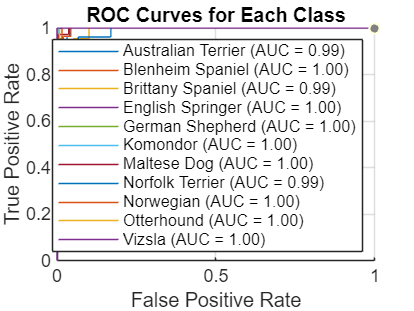

% Prepare ROC Curves
numClasses = numel(categories(imds.Labels));
classLabels = categories(imds.Labels);  % Retrieve class labels
scores = predict(netTransfer, augmentedTestData);
trueLabels = double(categorical(testDataTrueLabel));
figure;
hold on;

for i = 1:numClasses
    [X, Y, T, AUC] = perfcurve(trueLabels == i, scores(:, i), true);
    plot(X, Y, 'DisplayName', sprintf('%s (AUC = %.2f)', classLabels{i}, AUC));
end

xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for Each Class');
legend show;
grid on;